# Lab 5. Filters

## R-C Low-Pass Filter

Presentado por:

- Juan Esteban Diaz Delgado

- Nicolas Andres Yate Vargaz

- Brandon 


R = 100;
C = 22e-6;
Vi = 10;
Vrms = 10/sqrt(2);
Frequency = 1e3;

Fc = 1/(2*pi*C*R) %Frecuencia de corte

Fc = 72.3432


frecuency = logspace(0,7,1500);

Xc = 1./(2*pi*frecuency*C);

ganancia_tesion = Xc./(sqrt(R^2+Xc.^2))

ganancia_tesion =     0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9997    0.9997    0.9997    0.9997    0.9997



teta = -atand(R./Xc) %Angulo

teta =    -0.7919   -0.8005   -0.8092   -0.8179   -0.8267   -0.8357   -0.8447   -0.8538   -0.8631   -0.8724   -0.8818   -0.8914   -0.9010   -0.9107   -0.9206   -0.9305   -0.9406   -0.9508   -0.9610   -0.9714   -0.9819   -0.9925   -1.0033   -1.0141   -1.0251   -1.0361   -1.0473   -1.0587   -1.0701   -1.0817   -1.0934   -1.1052   -1.1171   -1.1292   -1.1414   -1.1537   -1.1662   -1.1788   -1.1916   -1.2044   -1.2174   -1.2306   -1.2439   -1.2573   -1.2709   -1.2847   -1.2986   -1.3126   -1.3268   -1.3411


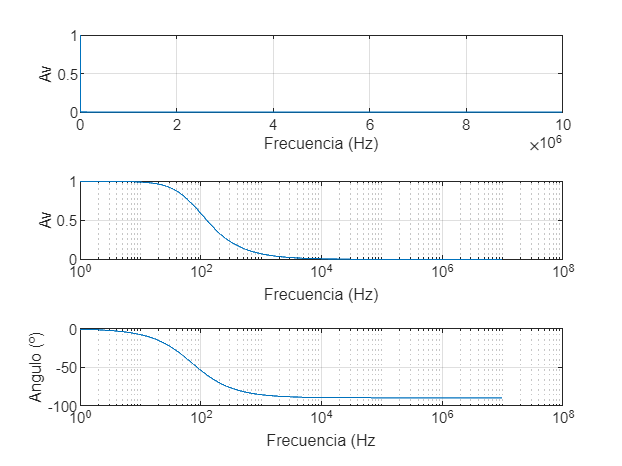


tiledlayout(3,1)

nexttile
plot(frecuency,ganancia_tesion)
grid on
ylabel('Av')
xlabel('Frecuencia (Hz)')

nexttile
semilogx(frecuency,ganancia_tesion)
grid on
ylabel('Av')
xlabel('Frecuencia (Hz)')

nexttile
semilogx(frecuency,teta)
grid on
ylabel('Angulo (º)')
xlabel('Frecuencia (Hz')

## R-C High-Pass Filter

R1 = 100;
C1 = 22e-6;
Vi1 = 10;
Xc1 = 1./(2*pi*frecuency*C1);
Frequency2 = 40;
Fc1 = 1/(2*pi*C*R) %Frecuencia de corte

Fc1 = 72.3432

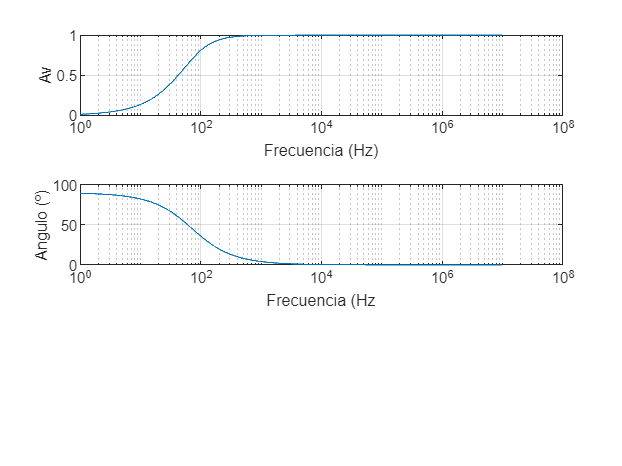


ganancia_tesion1 = R1./(sqrt(R1^2+Xc1.^2));

teta1 = atand(Xc1./R1);

tiledlayout(3,1)
nexttile
semilogx(frecuency,ganancia_tesion1)
grid on
ylabel('Av')
xlabel('Frecuencia (Hz)')

nexttile
semilogx(frecuency,teta1)
grid on
ylabel('Angulo (º)')
xlabel('Frecuencia (Hz')

## Band-Pass Filter

L = 2.7e-3;
C2 = 0.543e-6;
R2 = 100;
Rload = 120e3;
Vi2 = Vi;
Fc2 = 1./(2*pi*sqrt(L*C2)) %Frecuencia de corte

Fc2 = 4.1566e+03

Frequency3 = 1.8e6;
Xl3 = (2*pi*frecuency*L);
Xc3 = 1./(2*pi*frecuency*C2);

Av3 = (Rload./(sqrt((R2+Rload).^2+(Xl3-Xc3).^2)));

teta2 = -atand((-Xc3+Xl3)./(R2+Rload)) %Angulo

teta2 =    67.7185   67.5015   67.2829   67.0626   66.8406   66.6170   66.3918   66.1649   65.9363   65.7061   65.4743   65.2408   65.0057   64.7689   64.5306   64.2906   64.0490   63.8057   63.5609   63.3145   63.0665   62.8169   62.5658   62.3131   62.0589   61.8031   61.5457   61.2869   61.0266   60.7648   60.5015   60.2367   59.9705   59.7029   59.4338   59.1633   58.8915   58.6183   58.3437   58.0678   57.7907   57.5122   57.2324   56.9514   56.6692   56.3858   56.1011   55.8154   55.5285   55.2404


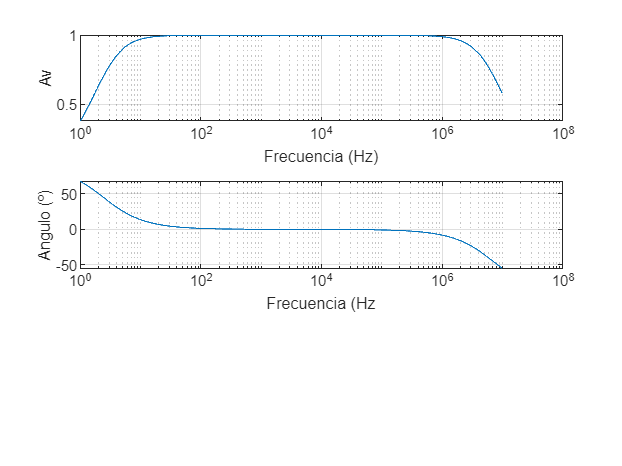




tiledlayout(3,1)
nexttile
semilogx(frecuency,Av3)
grid on
ylabel('Av')
xlabel('Frecuencia (Hz)')

nexttile
semilogx(frecuency,teta2)
grid on
ylabel('Angulo (º)')
xlabel('Frecuencia (Hz')

## Band-Stop Filter

R3 = 1.5e3;
R4 = 100;
L1 = 0.338e-3;
C3 = 22e-6;
Frequency4 = 1.8e6;
Xl4 = (2*pi*frecuency*L1);
Xc4 = 1./(2*pi*frecuency*C3);

Fc4 = 1./(2*pi*sqrt(L1*C3)) %Frecuencia de corte

Fc4 = 1.8457e+03

Av4 = sqrt((R4)^2+(Xl4-Xc4).^2)./(sqrt((R3+R4)^2+(Xl4-Xc4).^2));
teta3 = (atand((Xl4-Xc4)/(R4))-atand((Xl4-Xc4)/(R3+R4)))

teta3 =   -11.6793  -11.8013  -11.9244  -12.0488  -12.1743  -12.3011  -12.4291  -12.5583  -12.6887  -12.8204  -12.9534  -13.0876  -13.2230  -13.3598  -13.4978  -13.6371  -13.7778  -13.9197  -14.0629  -14.2075  -14.3534  -14.5007  -14.6493  -14.7992  -14.9505  -15.1032  -15.2572  -15.4127  -15.5695  -15.7277  -15.8874  -16.0484  -16.2108  -16.3747  -16.5400  -16.7067  -16.8749  -17.0445  -17.2155  -17.3880  -17.5620  -17.7374  -17.9143  -18.0926  -18.2725  -18.4538  -18.6365  -18.8208  -19.0065  -19.1937


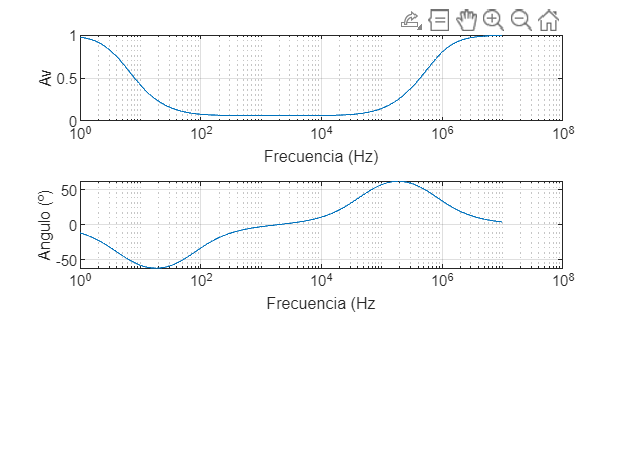




tiledlayout(3,1)
nexttile
semilogx(frecuency,Av4)
grid on
ylabel('Av')
xlabel('Frecuencia (Hz)')

nexttile
semilogx(frecuency,teta3)
grid on
ylabel('Angulo (º)')
xlabel('Frecuencia (Hz')